
Xdata = allWaveforms;
auto = trainAutoencoder(Xdata,200,'MaxEpochs',250,...
    'EncoderTransferFunction','satlin',...
    'DecoderTransferFunction','purelin');


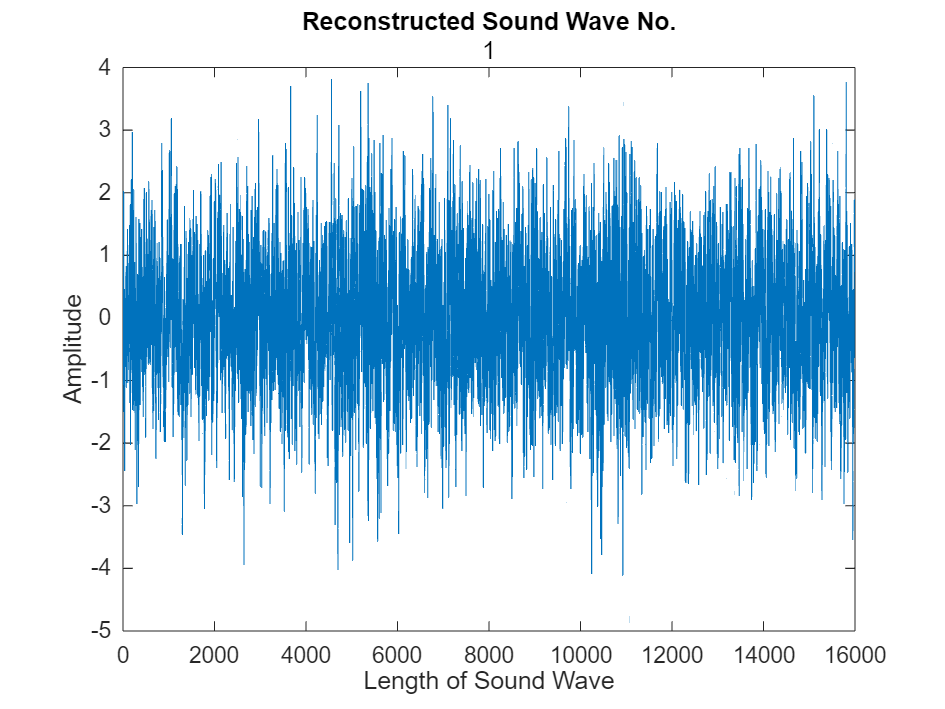

ReconX = predict(auto, Xdata);
sampnum = 1;
plot(ReconX(:,sampnum));
title("Reconstructed Sound Wave No.",sampnum)
xlabel('Length of Sound Wave');
ylabel('Amplitude');

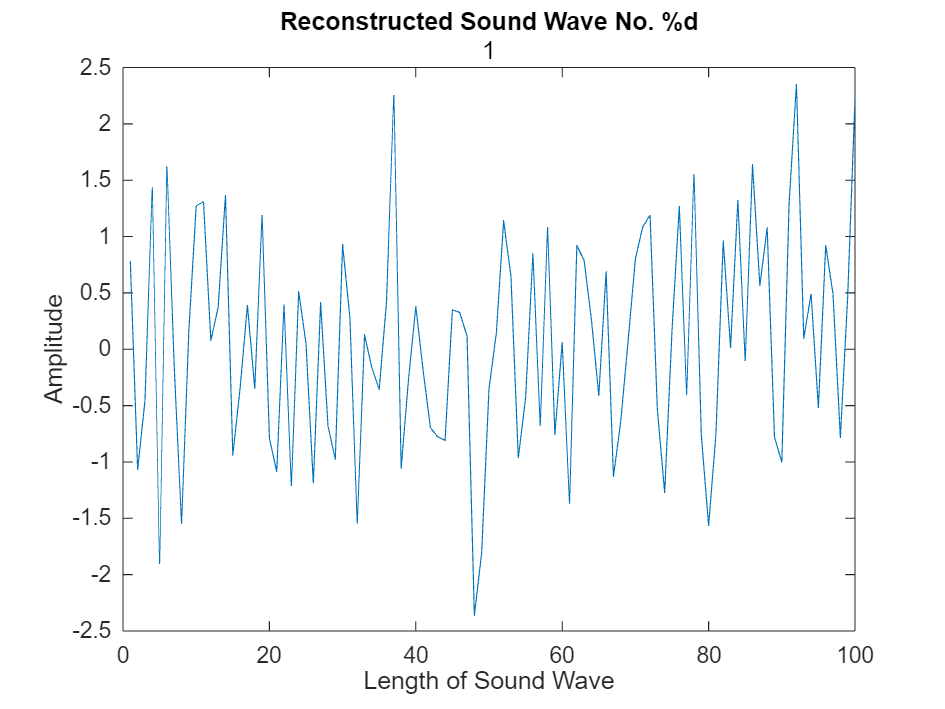


plot(allWaveforms(:,sampnum));
title("Reconstructed Sound Wave No. %d",sampnum)
xlabel('Length of Sound Wave');
ylabel('Amplitude');

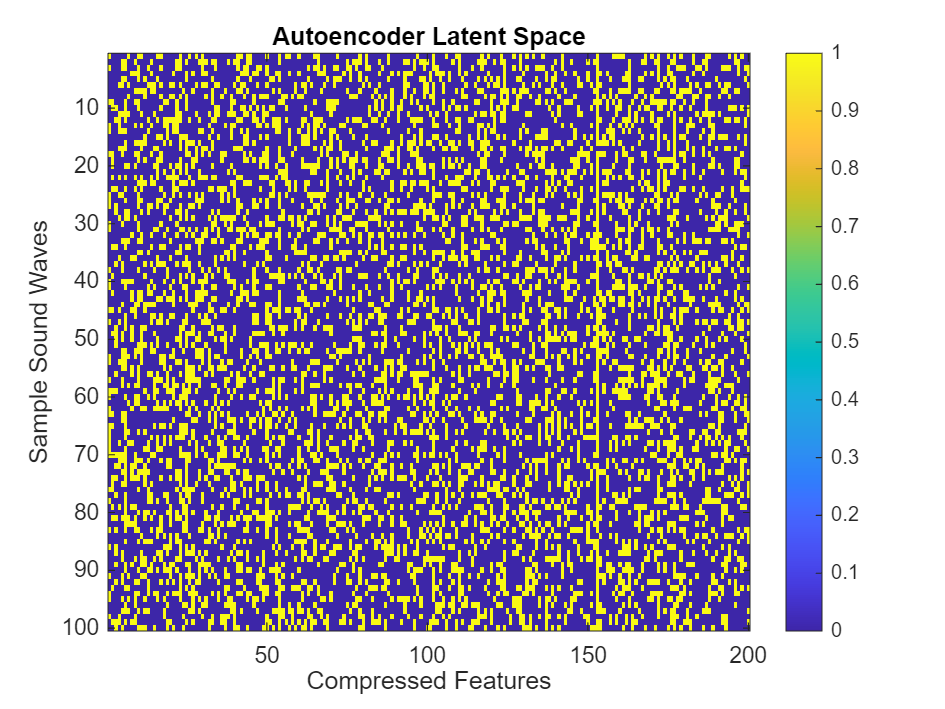


% Visuals Galore

% Encode all features using the trained autoencoder
normalEncodedFeatures = encode(auto, allWaveforms');
abnormalEncodedFeatures = encode(auto, allAbnormalWaveforms');

% Visualize the autoencoder weights
figure;
imagesc(normalEncodedFeatures');
colorbar;
xlabel('Compressed Features');
ylabel('Sample Sound Waves');
title('Autoencoder Latent Space');

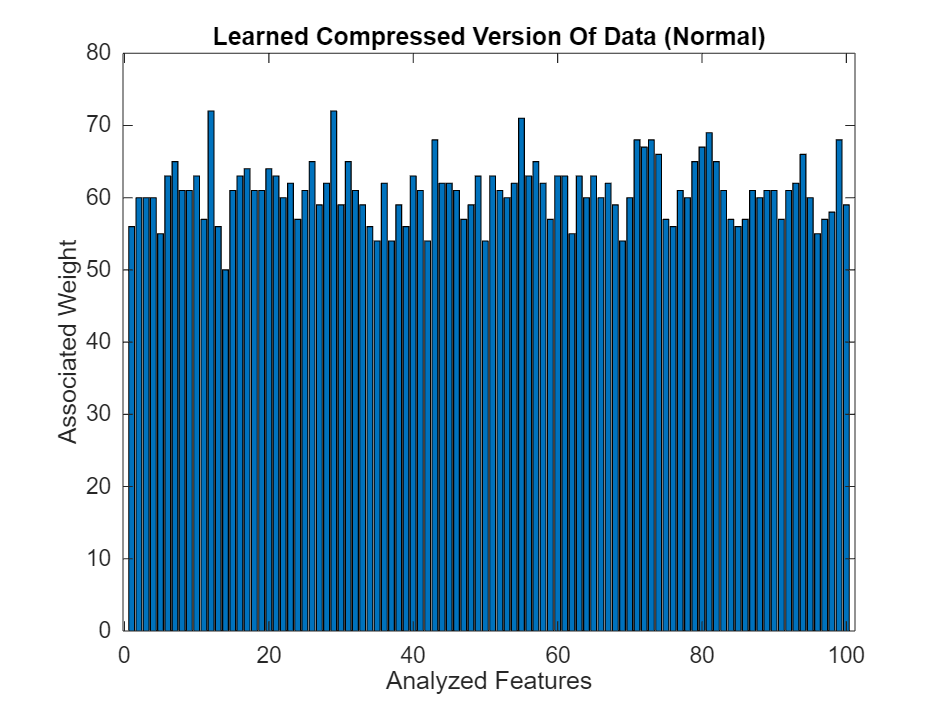



featureNum = size(normalEncodedFeatures, 2); overallWeight = zeros(featureNum,1); colW = [];
for featiter = 1:featureNum
    colW = normalEncodedFeatures(:,featiter);
    overallWeight(featiter) = sum(colW,1);
end
figure;
bar(overallWeight');
title('Learned Compressed Version Of Data (Normal)')
xlabel("Analyzed Features");
ylabel("Associated Weight"); 

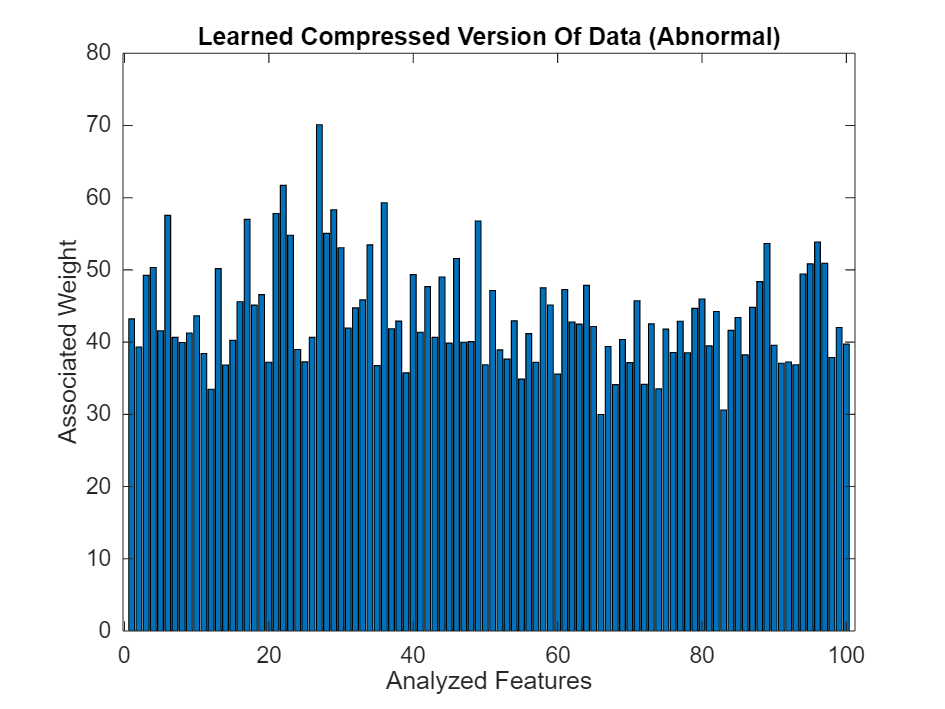


abnfeatureNum = size(abnormalEncodedFeatures, 2); abnoverallWeight = zeros(abnfeatureNum,1); abncolW = [];
for abnfeatiter = 1:abnfeatureNum
    abncolW = abnormalEncodedFeatures(:,abnfeatiter);
    abnoverallWeight(abnfeatiter) = sum(abncolW,1);
end
figure;
bar(abnoverallWeight');
title('Learned Compressed Version Of Data (Abnormal)')
xlabel("Analyzed Features");
ylabel("Associated Weight"); 

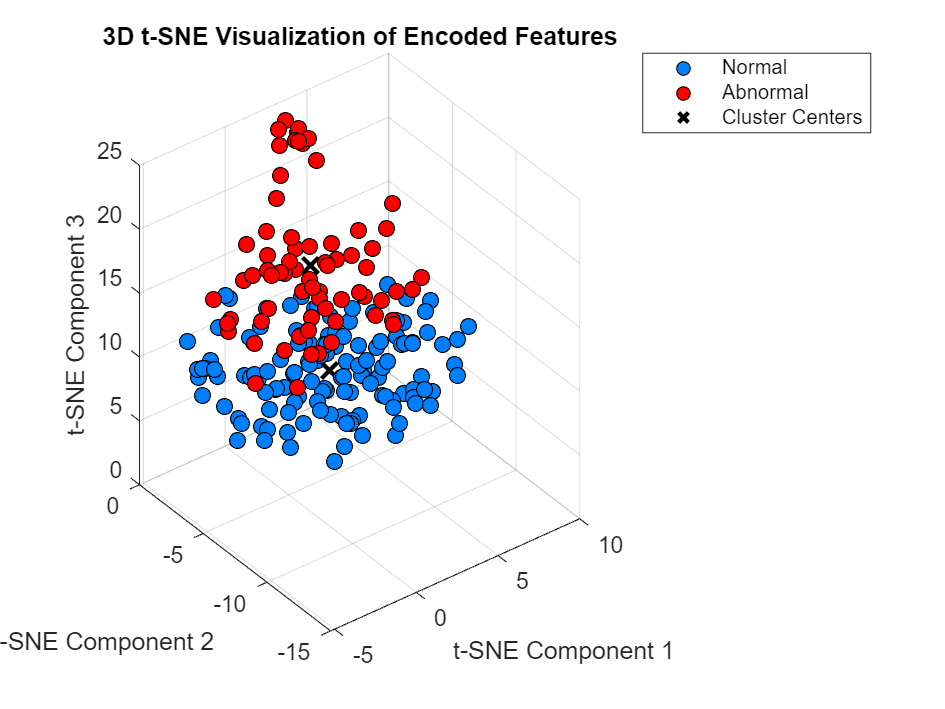

% Combine encoded features from autoencoder
combinedEncodedFeatures = [normalEncodedFeatures, abnormalEncodedFeatures];

% Create ground truth labels: 0 = Normal, 1 = Abnormal
trueLabels = [zeros(size(normalEncodedFeatures, 1), 1); ones(size(abnormalEncodedFeatures, 1), 1)];

% Apply t-SNE to reduce dimensions to 3D
mappedFeatures = tsne(combinedEncodedFeatures, 'NumDimensions', 3);

% Apply K-Means clustering (assume 2 clusters for normal/abnormal)
numClusters = 2;
[idx, C] = kmeans(mappedFeatures, numClusters);

% Determine which cluster corresponds to normal vs abnormal
cluster1_mean = mean(trueLabels(idx == 1)); % Check label distribution in Cluster 1
cluster2_mean = mean(trueLabels(idx == 2)); % Check label distribution in Cluster 2

% Assign cluster labels based on true labels
if cluster1_mean < cluster2_mean
    normalCluster = 1; abnormalCluster = 2;
else
    normalCluster = 2; abnormalCluster = 1;
end

% Assign colors for plotting
colors = [0 0.5 1; 1 0 0]; % Blue for Normal, Red for Abnormal
clusterColors = colors(idx == normalCluster + 1, :);

% Plot 3D t-SNE with cluster labels
figure;
scatter3(mappedFeatures(idx == normalCluster, 1), ...
         mappedFeatures(idx == normalCluster, 2), ...
         mappedFeatures(idx == normalCluster, 3), ...
         50, colors(1,:), 'filled', 'MarkerEdgeColor', 'k', 'DisplayName', 'Normal');

hold on;
scatter3(mappedFeatures(idx == abnormalCluster, 1), ...
         mappedFeatures(idx == abnormalCluster, 2), ...
         mappedFeatures(idx == abnormalCluster, 3), ...
         50, colors(2,:), 'filled', 'MarkerEdgeColor', 'k', 'DisplayName', 'Abnormal');

% Plot cluster centers
scatter3(C(:,1), C(:,2), C(:,3), 100, 'kx', 'LineWidth', 2, 'DisplayName', 'Cluster Centers');

% Labels & formatting
xlabel('t-SNE Component 1');
ylabel('t-SNE Component 2');
zlabel('t-SNE Component 3');
title('3D t-SNE Visualization of Encoded Features');
grid on;
legend('Normal', 'Abnormal', 'Cluster Centers');
hold off;

SVM Accuracy (Autoencoder Features): 95.00%


Iteration Number 1.000000

     9     1
     0    10



SVM Accuracy (Autoencoder Features): 92.50%


Iteration Number 2.000000

    18     2
     1    19



SVM Accuracy (Autoencoder Features): 88.33%


Iteration Number 3.000000

    25     5
     2    28



SVM Accuracy (Autoencoder Features): 91.25%


Iteration Number 4.000000

    34     6
     1    39



SVM Accuracy (Autoencoder Features): 93.00%


Iteration Number 5.000000

    44     6
     1    49



SVM Accuracy (Autoencoder Features): 91.67%


Iteration Number 6.000000

    51     9
     1    59



SVM Accuracy (Autoencoder Features): 92.14%


Iteration Number 7.000000

    62     8
     3    67



SVM Accuracy (Autoencoder Features): 88.75%


Iteration Number 8.000000

    65    15
     3    77



SVM Accuracy (Autoencoder Features): 70.56%


Iteration Number 9.000000

    43    47
     6    84



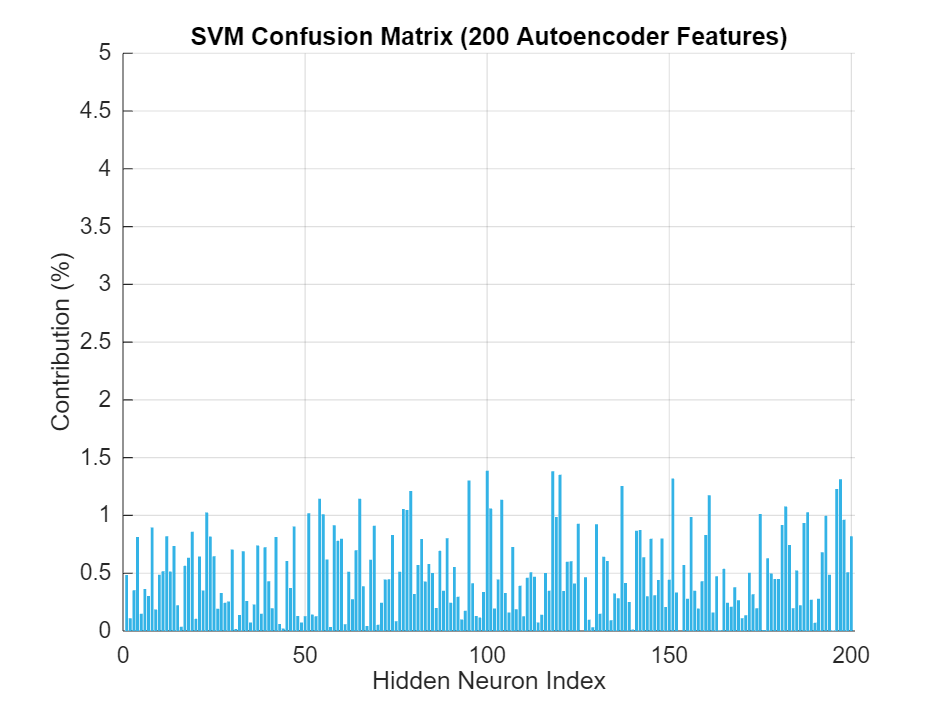


% Combine normal and abnormal features
combinedFeatures = [normalEncodedFeatures, abnormalEncodedFeatures];
combinedFeatures = combinedFeatures';

% Create corresponding labels: 0 for normal, 1 for abnormal
numNormal = size(normalEncodedFeatures, 2);
numAbnormal = size(abnormalEncodedFeatures, 2);
combinedLabels = [zeros(1, numNormal), ones(1, numAbnormal)];

% Convert features to table
featureTableAutoencoder = array2table(combinedFeatures);

% Extract feature matrix and labels
featureMatrixAutoencoder = table2array(featureTableAutoencoder);
labelsAutoencoder = combinedLabels';

% Check for NaNs in the feature matrix
if any(isnan(featureMatrixAutoencoder), 'all')
    error('Feature matrix contains NaN values!');
end

perfMod = 0.9;

% Loop through performance modifiers
for perfModiter = 0.1:0.1:perfMod
    % Split Data
    cv = cvpartition(labelsAutoencoder, 'HoldOut', perfModiter);
    XTrainAuto = featureMatrixAutoencoder(training(cv), :);
    YTrainAuto = labelsAutoencoder(training(cv));
    XTestAuto = featureMatrixAutoencoder(test(cv), :);
    YTestAuto = labelsAutoencoder(test(cv));

    % Train SVM Model with linear kernel
    svmModelAuto = fitcsvm(XTrainAuto, YTrainAuto, 'KernelFunction', 'linear', 'Standardize', true);

    % Predict on Test Data
    YPredAuto = predict(svmModelAuto, XTestAuto);
    accuracyAuto = sum(YPredAuto == YTestAuto) / length(YTestAuto);
    fprintf('SVM Accuracy (Autoencoder Features): %.2f%%\n', accuracyAuto * 100);
    fprintf('Iteration Number %f%\n', perfModiter/0.1);
    cauto=confusionmat(YTestAuto, YPredAuto);
    disp(cauto);

    % Calculate Feature Contributions
    svmWeightsAuto = svmModelAuto.Beta;
    featureContributionAuto = abs(svmWeightsAuto) / sum(abs(svmWeightsAuto)) * 100;

    % Create bar plot that updates smoothly
    clf; % Clear figure for fresh plot
    hold on;

    % Animate the bars growing
    numFeatures = length(featureContributionAuto);
    barHeights = zeros(1, numFeatures);
    numSteps = 20;  % Number of steps for animation

    for step = 1:numSteps
        barHeights = featureContributionAuto * (step / numSteps);
        bar(barHeights, 'FaceColor', [0.2, 0.7, 0.9]);
        
        % Labels and formatting
        xlabel('Hidden Neuron Index');
        ylabel('Contribution (%)');
        title(sprintf('Autoencoder SVM Feature Importance (200 Learned Features) - Iter %.0f, Acc: %.2f%%', perfModiter/0.1, accuracyAuto * 100));
        axis([0 numFeatures+1 0 5]);
        grid on;
        title('SVM Confusion Matrix (200 Autoencoder Features)'); 
        drawnow;  % Forces MATLAB to render the updated bars immediately
    end

    hold off;
end